## Solving dual equations

### Equation 1:


$$\alpha s_b^{DL}(\alpha)=(1-\alpha) s_a^{DL}$$


where $s_a^{DL}(\alpha)=\log_2(1+SNR_a^{DL}(\alpha))=\log_2(1+\frac{P_a^{DL}(\alpha)}{(1-\alpha)N_0B})$

            
$$s_b^{DL}(\alpha)=\log_2(1+SNR_b^{DL}(\alpha))=\log_2(1+\frac{P_b^{DL}(\alpha)}{\alpha N_0B})$$


Power equations:


$$    P_a^{DL}=\frac{1}{(\lambda_2-\lambda_z)(\cos^{-1}(\frac{p}{r_a}))}\int_{0}^{\cos^{-1}(\frac{p}{r_a})}\int_{\lambda_z}^{\lambda_2}P_{s}\frac{\lambda^2cos^2\theta}{(4\pi)^2p^2}d\lambda d\theta\\$$


        
$$    =P_s\frac{1}{(4\pi)^2p^2}\frac{\lambda_2^2+\lambda_2\lambda_z+\lambda_z^2}{3}\frac{\sin(2\cos^{-1}\frac{p}{r_a})+2\cos^{-1}\frac{p}{r_a}}{4\cos^{-1}(\frac{p}{r_a})}\\$$


        
$$
=P_s\frac{1}{(4\pi)^2p^2}\frac{\lambda_2^2+\lambda_2\lambda_z+\lambda_z^2}{3}[\frac{p\sqrt{r_a^2-p^2}}{2r_a^3\cos^{-1}(\frac{p}{r_a})}+\frac{1}{2}]$$



$$P_b^{DL}=\frac{1}{\lambda_z-\lambda_1}\int_{\lambda_1}^{\lambda_z}P_{m}\frac{G_m\lambda^2}{(4\pi)^2Ld_b^2}d\lambda$$


        
$$=\frac{P_m}{\lambda_z-\lambda_1}\frac{G_m}{(4\pi)^2d_b^2}\frac{\lambda_z^3-\lambda_1^3}{3}}$$


        
$$=P_m\frac{G_m}{(4\pi)^2d_b^2}\frac{\lambda_z^2+\lambda_z\lambda_1+\lambda_1^2}{3}$$


The range of wavelengths is small since the frequency range is large, hence, we can try approximating the integration across wavelengths, using a single Riemann midpoint sum:


$$\int_a^{a+\delta}f(x)dx \approx \delta f(\frac{2a+\delta}{2})$$


Then,


$$P_b^{DL}=P_m\frac{G_m}{(4\pi)^2d_b^2}(\frac{\lambda_1+\lambda_z}{2})^2$$



$$P_a^{DL}=P_s\frac{1}{(4\pi)^2p^2}[\frac{p\sqrt{r_a^2-p^2}}{2r_a^3\cos^{-1}(\frac{p}{r_a})}+\frac{1}{2}](\frac{\lambda_2+\lambda_z}{2})^2$$


%assume 1 carrier
Pm=10; %mbs power-40dBm
Ps=10; %sbs power-40dBm
Pu=0.092; %user power (earlier: 0.092)
Gm=1.5; %mbs directionality
Gs=1.5; %sbs directionality
d_b=4e3; %mbs-sbs distance
r_a=1e3; %region of coverage for sbs
p=100; %perpendicular distance between user and rail track
N0=3.9811e-21; %noise psd (-174 dBm)
c=3e8; %speed of light
f1=2.4e9; %start of bandwidth
f2=2.5e9; %stop of bandwidth
B=f2-f1; %bandwidth of sbs

syms alpha beta

Tower power requirements taken from:

[https://www.fierce-network.com/tech/5g-base-stations-use-a-lot-more-energy-than-4g-base-stations-says-mtn](https://www.fierce-network.com/tech/5g-base-stations-use-a-lot-more-energy-than-4g-base-stations-says-mtn)

UE Transmit power values taken from:

[https://ieeexplore.ieee.org/document/9515027](https://ieeexplore.ieee.org/document/9515027)

(M. Nedelcu, V. Niţu and T. Petrescu, "Uplink power levels of user equipment in commercial 4G and 5G networks," 2021 13th International Conference on Electronics, Computers and Artificial Intelligence (ECAI), Pitesti, Romania, 2021, pp. 1-4, doi: 10.1109/ECAI52376.2021.9515027)

[**Update**: 15/1]: Sir's inputs taken, as well as source: [https://www.ee.iitb.ac.in/~mwave/Cell-tower-rad-report-WB-Environ-Oct2011.pdf](https://www.ee.iitb.ac.in/~mwave/Cell-tower-rad-report-WB-Environ-Oct2011.pdf) -a report about hazards. Changes made:

- Base station powers from kW to W range

Preliminary definitions done. Let's define secondary-level defs.

fz=f1+alpha*B;
lambda1=c/f1; lambda2=c/f2;
lambdaz=c/fz;
p_dl_b=28.2628*Pm*Gm/(4*pi*d_b)^2*(lambda1+lambdaz)^2/4;
p_dl_a=1.0855*Ps/(4*pi*p)^2*((p*sqrt(r_a^2-p^2))/(2*r_a^3*acos(p/r_a))+1/2)*(lambdaz+lambda2)^2/4;

snr_dl_b=p_dl_b/(N0*alpha*B);
snr_dl_a=p_dl_a/(N0*(1-alpha)*B);

eq1= alpha*log2(1+snr_dl_b)==(1-alpha)*log2(1+snr_dl_a);
fplot([lhs(eq1), rhs(eq1)],[0,1]);
vpasolve(eq1,alpha,[0,1])

$$ans = 0.5748016289576054602505339622734$$

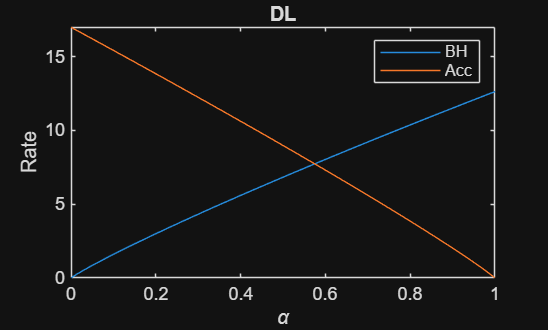

title("DL");
xlabel("\alpha");
ylabel("Rate");
legend(["BH","Acc"]);

Observation: 1) Decreasing Pm or increasing Ps increases α.

                     2) Decreasing f2-f1 leads to increase in α, but it's not just the absolute difference: increasing f2 leads to a big decrease and increasing f1 leads to a big increase. Higher the ranges of f, higher α tends to be.

### Equation-2:


$$\beta s_b^{UL}(\beta)=(1-\beta)s_a^{UL}(\beta)$$



$$P_b^{UL}=\frac{1}{\lambda_y-\lambda_1}\int_{\lambda_1}^{\lambda_y}P_{s}\frac{\lambda^2}{(4\pi)^2Ld_b^2}d\lambda$$


        
$$=\frac{P_s}{(4\pi)^2 d_b^2}(\frac{\lambda_1+\lambda_y}{2})^2$$



$$P_a^{UL}=P_u\frac{1}{(4\pi)^2p^2}[\frac{p\sqrt{r_a^2-p^2}}{2r_a^3\cos^{-1}(\frac{p}{r_a})}+\frac{1}{2}](\frac{\lambda_2+\lambda_y}{2})^2$$


fy=f1+beta*B;
lambday=c/fy;
p_ul_b=Ps/(4*pi*d_b)^2*(lambda1+lambday)^2/4;
p_ul_a=Pu/(4*pi*p)^2*((p*sqrt(r_a^2-p^2))/(2*r_a^3*acos(p/r_a))+1/2)*(lambday+lambda2)^2/4;

snr_ul_b=p_ul_b/(N0*beta*B);
snr_ul_a=p_ul_a/(N0*(1-beta)*B);

eq2= beta*log2(1+snr_ul_b)==(1-beta)*log2(1+snr_ul_a);
fplot([lhs(eq2), rhs(eq2)],[0,1]);
vpasolve(eq2,beta,[0,1])

$$ans = 0.58561185953568986504719697414367$$

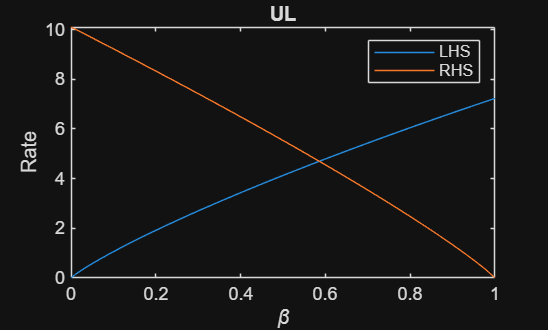

title("UL");
xlabel("\beta");
ylabel("Rate");
legend(["LHS","RHS"]);

### Issues to solve:

- As soon as the frequency ranges hit more nominal values, the ratio peaks to the high 90%s, which is unreasonable.

# 15/1:

We want to observe the variance of Rx. Power/SNR w.r.t. α.

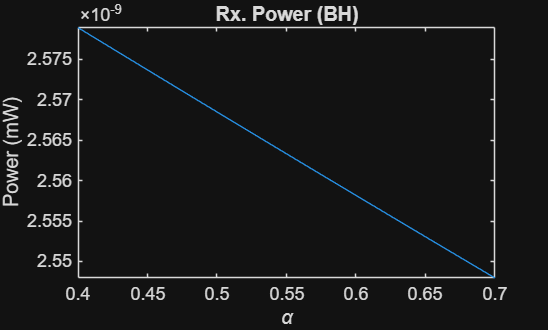

fplot(p_dl_b,[0.4,0.7])
title("Rx. Power (BH)");
xlabel("\alpha");
ylabel("Power (mW)");

# 21/1:

When using the original integral, $\lambda_1$ < $\lambda_z
$ but the integral shows in the opposite direction; however this doesn't affect the integral result aside from a negative; and the simplified expression due to commutativity.

# 23/1:

**Issue:** 1. 2d distances considered, 3D should have been considered

            2. Is the equation applicable with Fresnel distance?

0.38e-6 if distance not averaged and user at perpendicular dist

If distance averaged andn alpha=0:

p_samp_a=Ps/(4*pi*p)^2*((p*sqrt(r_a^2-p^2))/(2*r_a^3*acos(p/r_a))+1/2)*(lambda2)^2;
p_samp_b=Pm*Gm/(4*pi*d_b)^2*(lambda1)^2/4;

Function to calculate dBm:

function op=wdbm(ip,mode)
    %w->dBm or dBm to mW
    if mode=='w'
        op=10.*log10(ip)+30;
    elseif mode=="dBm"
            op=10.^(ip/10);
    else
        disp("not valid mode");
    end
end

Now, let's see the received power in dBm:

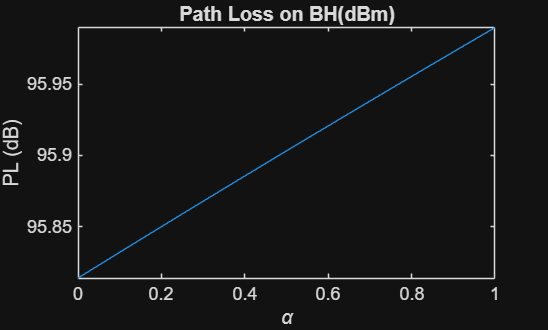

fplot(40-wdbm(p_dl_b,'w'),[0,1]);
title("Path Loss on BH(dBm)");
xlabel("\alpha");
ylabel("PL (dB)");

# 30/1:

We used the following calculator to find PL: 

[https://www.pasternack.com/t-calculator-fspl.aspx?](https://www.pasternack.com/t-calculator-fspl.aspx?)

[https://www.everythingrf.com/rf-calculators/free-space-path-loss-calculator](https://www.everythingrf.com/rf-calculators/free-space-path-loss-calculator) (for more precision)

Backhaul:

The PL obtained for d=1km, f=2.4GHz, $G_t=4.0547 dBi(1.5), G_r=0dBi(1)$: 95.99 dB (**95.98952483 dB)**

PL we obtained: 110.5018 dB

double(40-subs(wdbm(p_dl_b,'w'),1))

ans = 95.9896

PL to be removed then is ~14.5123dB. We drop this by multiplying received power with a fraction.

Constant factor:${10}^{1\ldotp 45123} ~28\ldotp 2638$

Access:

Over access link: What is the average distance we can use to search for PL:

Effective denominator factor is: $\frac{p}{\sqrt{\frac{p\sqrt{r_a^2-p^2}}{2r_a^3\arccos(\frac{p}{r_a})}+\frac{1}{2}}}$~141.4166m

PL obtained on access for d=141.4166m, f=2.4GHz, and no directionalities: **83.05423266 dB**

PL we obtained: 83.4106 dB

double(40-subs(wdbm(p_dl_a,'w'),1))

ans = 83.0543

PL to be removed: 0.3564 dB

Constant factor: ${10}^{0\ldotp 03564} ~1\ldotp 0855$ 

PL obtained on access for Gs=1.5:  **78.99953266 dB**

PL we obtained: 81.6497 dB

PL to be removed: 1.6502 dB

Factor: ${10}^{0\ldotp 16502} ~1\ldotp 4622$

# 3/2:

Have negelcted variation of wavelength and determined a simpler expression:

$\alpha \log(1+\frac{2.4854*10^{3}}{\alpha})=(1-\alpha)\log(1+\frac{1.1453*10^{5}}{1-\alpha})$ ([Derivation](matlab:open('.\iab_derv_1.pdf')) with mbs gain=1 instead of 1.5)

Z=2.4854e3*1.5;
eq3=alpha*log2(1+Z/alpha)==(1-alpha)*log2(1+46.0831*Z/(1-alpha));
%double(subs(rhs(eq3),0));
vpasolve(eq3,alpha, [0,1])

$$ans = 0.59732913423432615691405736710085$$

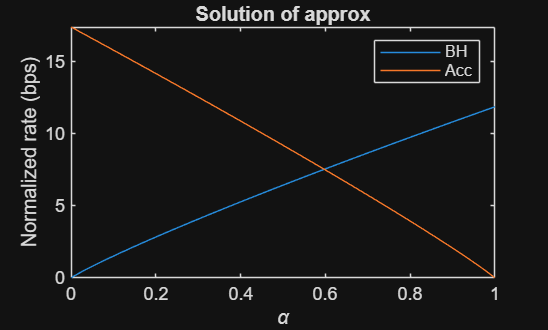


figure;
fplot([lhs(eq3), rhs(eq3)],[0,1]);
title("Solution of approx");
legend(["BH","Acc"]);
xlabel("\alpha"); ylabel("Normalized rate (bps)");

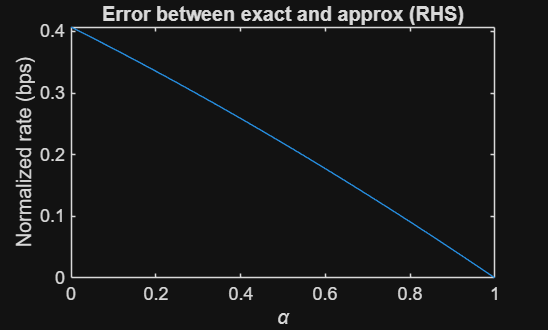


% figure;
% plot(double(subs(lhs(eq3),[1e-12,1])));
% title("LHS of approx");
% xlabel("\alpha"); ylabel("Normalized rate (bps)");

figure;
fplot(rhs(eq3)-rhs(eq1),[0,1]);
title("Error between exact and approx (RHS)");
xlabel("\alpha"); ylabel("Normalized rate (bps)");

# 4/2:

Update: N0: 1e-12 W to -170dBm

A solution appears now, this could be possibly because the earlier analyzis was conducted in a noise-limited environment. The solution isn't much dependent on frequency, which is another objective we were trying to reach at.

# 10/2:

How does the approximate method compare against the more precise method?

#### 1. Time performance

meas_prec=@() vpasolve(eq1,alpha,[0,1]);
meas_app=@() vpasolve(eq3, alpha, [0,1]);
time_prec=timeit(meas_prec);
time_app=timeit(meas_app);

Saved about 22 ms.

#### 2. Complexity

Mostly dependent on vpasolve, but the complexity can be said to be equal with both algorithms

#### 3. Alternate methods for analyzis

This include profiling and using alternate measures to solve so as get less abstract than vpasolve, but we leave this for later.

#### 4. Error

This is another primary concern along with 1. The parameter of approximation is frequency, hence the error is to be taken w.r.t. the BW. Attempts to plot a graph is being made, but safe to say, the errors rise once you are out of the MHz range, but we are within it.